# Logistic Regression

build a logistic regression model to predict whether a student gets admitted into a university  

## 1.1 **Visualizing the data**

The first two columns contains the exam scores and the third column contains the label.

data = load('./ex2data1.txt')

data =    34.6237   78.0247         0
   30.2867   43.8950         0
   35.8474   72.9022         0
   60.1826   86.3086    1.0000
   79.0327   75.3444    1.0000
   45.0833   56.3164         0
   61.1067   96.5114    1.0000
   75.0247   46.5540    1.0000
   76.0988   87.4206    1.0000
   84.4328   43.5334    1.0000


x = data(:, [1, 2]); y = data(:, 3);
x, y

x =    34.6237   78.0247
   30.2867   43.8950
   35.8474   72.9022
   60.1826   86.3086
   79.0327   75.3444
   45.0833   56.3164
   61.1067   96.5114
   75.0247   46.5540
   76.0988   87.4206
   84.4328   43.5334


y =      0
     0
     0
     1
     1
     0
     1
     1
     1
     1


找到正类的行

pos = find(y == 1)

pos =      4
     5
     7
     8
     9
    10
    13
    14
    16
    17


neg = find(y == 0)

neg =      1
     2
     3
     6
    11
    12
    15
    18
    21
    23


要画两个分数，而不是 x 和 y。

同时要区分正类负类

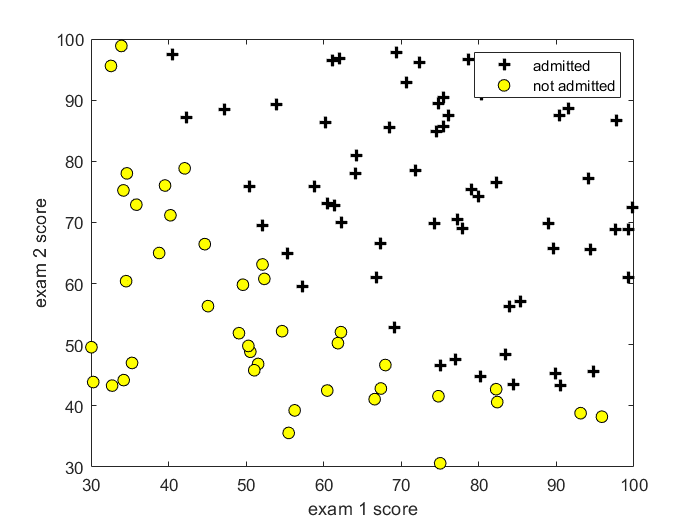

figure;
% x 轴 exam 1 的分数，y 轴 exam 2 的分数
plot(x(pos, 1), x(pos, 2), 'k+', 'LineWidth', 2, 'MarkerSize', 7);
xlabel('exam 1 score'); ylabel('exam 2 score');
hold on;
plot(x(neg, 1), x(neg, 2), 'ko', 'MarkerFaceColor', 'y', 'MarkerSize', 7); legend('admitted', 'not admitted'); hold off; 

## 1.2 implementation

## 1.2.1 **Warmup exercise: sigmoid function**


$$h_\theta(x) = g(\theta^Tx)\\
g(z) = \frac{1}{1 + e^{-z}}$$


sigmoid(0)

ans = 0.5000

## 1.2.2 **Cost function and gradient**

cost 如下：


$$J\left( \theta  \right)=\frac{1}{m}\sum\limits_{i=1}^{m}{[-{{y}^{(i)}}\log \left( {h_\theta}\left( {{x}^{(i)}} \right) \right)-\left( 1-{{y}^{(i)}} \right)\log \left( 1-{h_\theta}\left( {{x}^{(i)}} \right) \right)]}$$


这个是化简后的，原本的思想就是一个分段判断。同时 gradient 如下：


$$\theta_j := \theta_j - \alpha \frac{1}{m}\sum\limits_{i=1}^{m}{{\left( {h_\theta}\left( \mathop{x}^{\left( i \right)} \right)-\mathop{y}^{\left( i \right)} \right)}}\mathop{x}_{j}^{(i)}$$


和线性回归的梯度下降公式长得一样，但 h 不一样。

initial_theta = zeros(size(x, 2) + 1, 1); % 给 \theta_0
X = [ones(length(y), 1), x] % \theta_0 的

X =     1.0000   34.6237   78.0247
    1.0000   30.2867   43.8950
    1.0000   35.8474   72.9022
    1.0000   60.1826   86.3086
    1.0000   79.0327   75.3444
    1.0000   45.0833   56.3164
    1.0000   61.1067   96.5114
    1.0000   75.0247   46.5540
    1.0000   76.0988   87.4206
    1.0000   84.4328   43.5334


costFunction(initial_theta, X, y)

ans = 0.6931

## 1.2.3 **Learning parameters using ***fminunc*

options = optimset('GradObj', 'on', 'MaxIter', 400);

[theta, cost] = fminunc(@(t)(costFunction(t, X, y)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the optimality tolerance.

<stopping criteria details>



cost,theta

cost = 0.2035

theta =   -25.1613
    0.2062
    0.2015


用更合适的初始参数，能够得到更小的损失

test_theta = [-24; 0.2; 0.2];
[cost_test, grad] = costFunction(test_theta, X, y);
cost_test

cost_test = 0.2183

X(:, 2:3)

ans =    34.6237   78.0247
   30.2867   43.8950
   35.8474   72.9022
   60.1826   86.3086
   79.0327   75.3444
   45.0833   56.3164
   61.1067   96.5114
   75.0247   46.5540
   76.0988   87.4206
   84.4328   43.5334


plot_x = [min(X(:,2))-2,  max(X(:,2))+2]

plot_x =    28.0588  101.8279


plot_y = (-1 ./ theta(3)).* (theta(2) .* plot_x + theta(1))

plot_y =    96.1660   20.6540


这里要求画决策边界，我还是看不懂卡这里了，故先跳过


$$\theta_0 + \theta_1x_1 + \theta_1x_2 = 0$$


用这个去变形，就能理解。

plot_x = [min(X(:,2))-2,  max(X(:,2))+2]; 
plot_y = [];


## 1.2.4 **Evaluating logistic regression**

sigmoid([1 45, 85] * theta)

ans = 0.7763

p = predict(theta, X)

p =      0
     0
     0
     1
     1
     0
     1
     0
     1
     1


fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 89.000000


# **2 Regularized logistic regression**

## **2.1 Visualizing the data**

data = load('ex2data2.txt')

data =     0.0513    0.6996    1.0000
   -0.0927    0.6849    1.0000
   -0.2137    0.6923    1.0000
   -0.3750    0.5022    1.0000
   -0.5132    0.4656    1.0000
   -0.5248    0.2098    1.0000
   -0.3980    0.0344    1.0000
   -0.3059   -0.1923    1.0000
    0.0167   -0.4042    1.0000
    0.1319   -0.5139    1.0000


x = data(:, 1:2)

x =     0.0513    0.6996
   -0.0927    0.6849
   -0.2137    0.6923
   -0.3750    0.5022
   -0.5132    0.4656
   -0.5248    0.2098
   -0.3980    0.0344
   -0.3059   -0.1923
    0.0167   -0.4042
    0.1319   -0.5139


y = data(:, 3)

y =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


m = length(y);
X = [ones(m, 1), x]

X =     1.0000    0.0513    0.6996
    1.0000   -0.0927    0.6849
    1.0000   -0.2137    0.6923
    1.0000   -0.3750    0.5022
    1.0000   -0.5132    0.4656
    1.0000   -0.5248    0.2098
    1.0000   -0.3980    0.0344
    1.0000   -0.3059   -0.1923
    1.0000    0.0167   -0.4042
    1.0000    0.1319   -0.5139


pos = (y == 1)

pos = 118×1 logical 数组
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


neg = (y == 0)

neg = 118×1 logical 数组
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


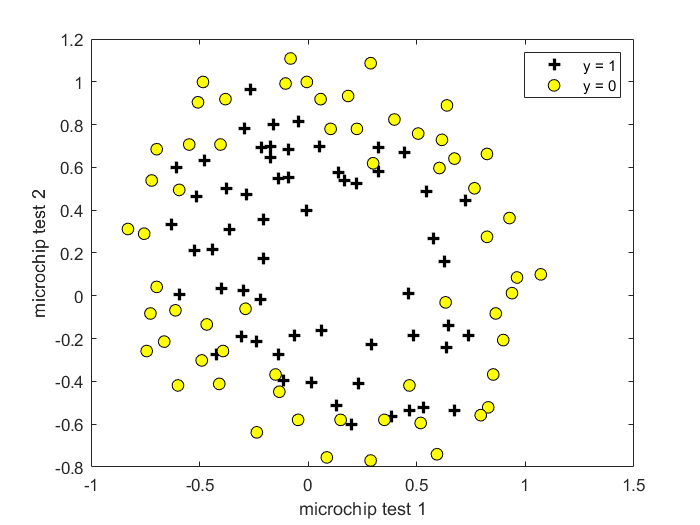

figure;
% x 轴 exam 1 的分数，y 轴 exam 2 的分数
plot(x(pos, 1), x(pos, 2), 'k+', 'LineWidth', 2, 'MarkerSize', 7);
xlabel('microchip test 1'); ylabel('microchip test 2');
hold on;
plot(x(neg, 1), x(neg, 2), 'ko', 'MarkerFaceColor', 'y', 'MarkerSize', 7); legend('y = 1', 'y = 0'); hold off; 

## 2.2 **Feature mapping**

利用此函数可以建立非线性的代价边界。


$$mapFeature(x) = [1, x_1, x_2, x_1^2, x_1x_2,x_2^2,x_1^3,..., x_1x_2^5, x_1^6]^T
$$


这里的 x1, x2 是两个 feature 的对应变量取值，在本次实验中就是 microchip test 1 的分数，和 Micochip test 2 的分数。

下文会有使用

## 2.3 **Cost function and gradient**

引入正则的逻辑回归代价函数如下：


$$J\left( \theta  \right)=\frac{1}{m}\sum\limits_{i=1}^{m}{[-{{y}^{(i)}}\log \left( {h_\theta}\left( {{x}^{(i)}} \right) \right)-\left( 1-{{y}^{(i)}} \right)\log \left( 1-{h_\theta}\left( {{x}^{(i)}} \right) \right)]}+\frac{\lambda }{2m}\sum\limits_{j=1}^{n}{\theta _{j}^{2}}$$


注意，不惩罚 $\theta_0$，所以关于它的梯度下降要分开来看。


$${\theta_0}:={\theta_0}-a\frac{1}{m}\sum\limits_{i=1}^{m}{(({h_\theta}({{x}^{(i)}})-{{y}^{(i)}})x_{0}^{(i)}})\\
{\theta_j}:={\theta_j}-a[\frac{1}{m}\sum\limits_{i=1}^{m}{({h_\theta}({{x}^{(i)}})-{{y}^{(i)}})x_{j}^{\left( i \right)}}+\frac{\lambda }{m}{\theta_j}]$$


% Add Polynomial Features
% Note that mapFeature also adds a column of ones for us, so the intercept
% term is handled
X = mapFeature(X(:,2), X(:,3))

X =     1.0000    0.0513    0.6996    0.0026    0.0359    0.4894    0.0001    0.0018    0.0251    0.3424    0.0000    0.0001    0.0013    0.0176    0.2395    0.0000    0.0000    0.0001    0.0009    0.0123    0.1675    0.0000    0.0000    0.0000    0.0000    0.0006    0.0086    0.1172
    1.0000   -0.0927    0.6849    0.0086   -0.0635    0.4691   -0.0008    0.0059   -0.0435    0.3213    0.0001   -0.0005    0.0040   -0.0298    0.2201   -0.0000    0.0001   -0.0004    0.0028   -0.0204    0.1508    0.0000   -0.0000    0.0000   -0.0003    0.0019   -0.0140    0.1033
    1.0000   -0.2137    0.6923    0.0457   -0.1479    0.4792   -0.0098    0.0316   -0.1024    0.3317    0.0021   -0.0068    0.0219   -0.0709    0.2296   -0.0004    0.0014   -0.0047    0.0152   -0.0491    0.1590    0.0001   -0.0003    0.0010   -0.0032    0.0105   -0.0340    0.1100
    1.0000   -0.3750    0.5022    0.1406   -0.1883    0.2522   -0.0527    0.0706   -0.0946    0.1266    0.0198   -0.0265    0.0355   -0.0475    0.0636   

% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

% Set regularization parameter lambda to 1
lambda = 1;
[cost, grad] = costFunctionReg(initial_theta, X, y, lambda);
cost, grad

cost = 0.6931

grad =     0.0085
    0.0188
    0.0001
    0.0503
    0.0115
    0.0377
    0.0184
    0.0073
    0.0082
    0.0235


fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.693147


fprintf('Expected cost (approx): 0.693\n');

Expected cost (approx): 0.693


fprintf('Gradient at initial theta (zeros) - first five values only:\n');

Gradient at initial theta (zeros) - first five values only:


fprintf(' %f \n', grad(1:5));

 0.008475 
 0.018788 
 0.000078 
 0.050345 
 0.011501 


fprintf('Expected gradients (approx) - first five values only:\n');

Expected gradients (approx) - first five values only:


fprintf(' 0.0085\n 0.0188\n 0.0001\n 0.0503\n 0.0115\n');

 0.0085
 0.0188
 0.0001
 0.0503
 0.0115


## 2.3.1 **Learning parameters using **fminunc

options = optimset('GradObj', 'on', 'MaxIter', 400);
[theta, J, exit_flag] = fminunc(@(t)(costFunctionReg(t, X, y, lambda)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the optimality tolerance.

<stopping criteria details>



theta, J, exit_flag

theta =     1.2727
    0.6252
    1.1811
   -2.0200
   -0.9174
   -1.4316
    0.1240
   -0.3655
   -0.3572
   -0.1751


J = 0.5290

exit_flag = 1

## 2.4 **Plotting the decision boundary**

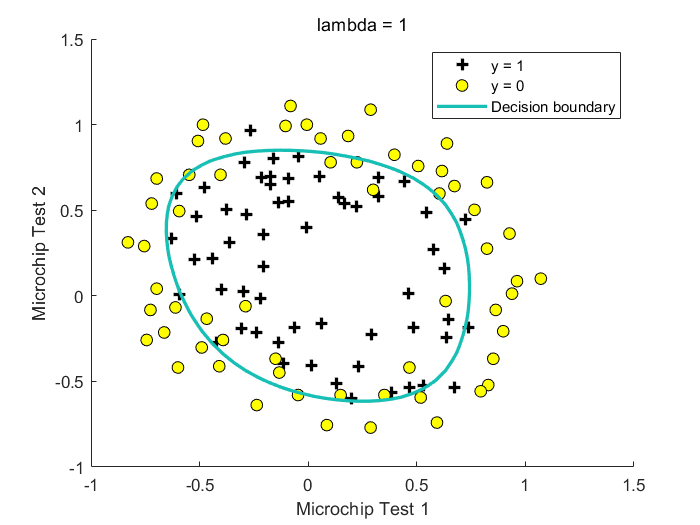

plotDecisionBoundary(theta, X, y);
hold on;
title(sprintf('lambda = %g', lambda))

% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')

legend('y = 1', 'y = 0', 'Decision boundary')
hold off;

Compute accuracy on our training set

p = predict(theta, X);

fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 83.050847


fprintf('Expected accuracy (with lambda = 1): 83.1 (approx)\n');

Expected accuracy (with lambda = 1): 83.1 (approx)


## 2.5 **Optional  exercises**

改变 $\lambda$ 来观察决策边界

减少 $\lambda$ 过多，过拟合。

lambda = 0;
[theta, J, exit_flag] = fminunc(@(t)(costFunctionReg(t, X, y, lambda)), initial_theta, options);


Solver stopped prematurely.

fminunc stopped because it exceeded the iteration limit,
options.MaxIterations = 400 (the selected value).



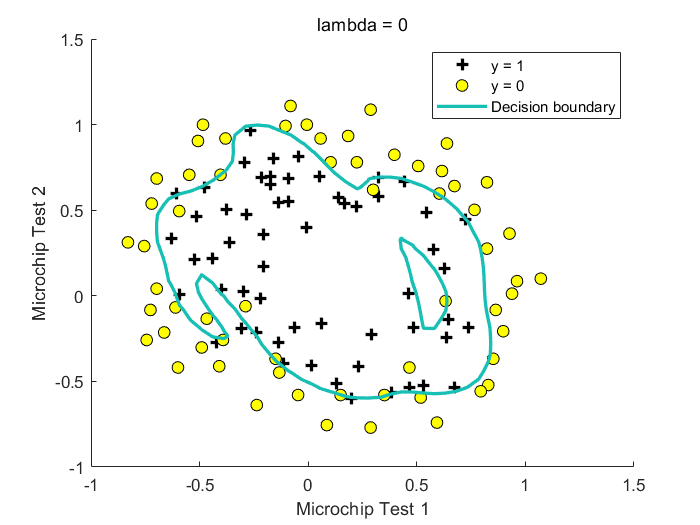

plotDecisionBoundary(theta, X, y);
hold on;
title(sprintf('lambda = %g', lambda))

% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')

legend('y = 1', 'y = 0', 'Decision boundary')
hold off;

p = predict(theta, X);
fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 88.983051


增加 $\lambda$ 过多 ，欠拟合

lambda = 100;
[theta, J, exit_flag] = fminunc(@(t)(costFunctionReg(t, X, y, lambda)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the optimality tolerance.

<stopping criteria details>



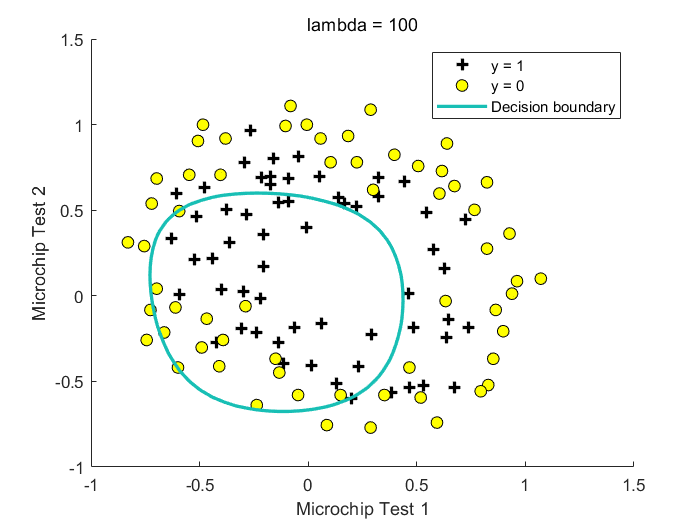

plotDecisionBoundary(theta, X, y);
hold on;
title(sprintf('lambda = %g', lambda))

% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')

legend('y = 1', 'y = 0', 'Decision boundary')
hold off;

p = predict(theta, X);
fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 61.016949


# 掌握不好的地方

- plotDecisionBoundary 中，关于直线边界和非线性边界

- predict 的编写中，如何把概率转为 0 或 1 的分类。

# 函数自定义


$$
g(z) = \frac{1}{1 + e^{-z}}$$


function g = sigmoid(z)
    g = 1 ./ (1 + exp(-z));
end


$$J\left( \theta  \right)=\frac{1}{m}\sum\limits_{i=1}^{m}{[-{{y}^{(i)}}\log \left( {h_\theta}\left( {{x}^{(i)}} \right) \right)-\left( 1-{{y}^{(i)}} \right)\log \left( 1-{h_\theta}\left( {{x}^{(i)}} \right) \right)]}
\\
\frac{1}{m}\sum\limits_{i=1}^{m}{{\left( {h_\theta}\left( \mathop{x}^{\left( i \right)} \right)-\mathop{y}^{\left( i \right)} \right)}}\mathop{x}_{j}^{(i)}
$$


function [J, grad] = costFunction_my(theta, X, y) % 结果 ok
    m = length(y);
    h_theta = sigmoid(X * theta);
    grad = sum((h_theta - y) .* X, 1) ;
    J = sum(-y .* log(h_theta) - (1 - y) .* log(1 - h_theta), 1) ./ m;
end

function [J, grad] = costFunction(theta, X, y)
    m = length(y);
    J = 0;
    grad = zeros(size(theta));
    
    h_theta = sigmoid(X * theta);
    J       = sum(-y .* log(h_theta) - (1 - y) .* log(1 - h_theta), 1) ./ m;
    
    grad = (X' * (h_theta - y)) ./ m; % 这个真的要有思维
    %grad = sum((h_theta - y) .* X, 1) ;
end


function p = predict(theta, X)
    m = size(X, 1); % Number of training examples
    
    % You need to return the following variables correctly
    p = zeros(m, 1);
    
    % 我想的还是用 if，要用如下方式， >= 0.5 就是正类
    k = sigmoid(X * theta) >= 0.5;
    p(k) = 1;
end


function out = mapFeature(X1, X2)
    % MAPFEATURE Feature mapping function to polynomial features
    %
    %   MAPFEATURE(X1, X2) maps the two input features
    %   to quadratic features used in the regularization exercise.
    %
    %   Returns a new feature array with more features, comprising of 
    %   X1, X2, X1.^2, X2.^2, X1*X2, X1*X2.^2, etc..
    %
    %   Inputs X1, X2 must be the same size
    %
    
    degree = 6;
    out = ones(size(X1(:,1)));
    for i = 1:degree
        for j = 0:i
            out(:, end+1) = (X1.^(i-j)).*(X2.^j);
        end
    end

end



$$J\left( \theta  \right)=\frac{1}{m}\sum\limits_{i=1}^{m}{[-{{y}^{(i)}}\log \left( {h_\theta}\left( {{x}^{(i)}} \right) \right)-\left( 1-{{y}^{(i)}} \right)\log \left( 1-{h_\theta}\left( {{x}^{(i)}} \right) \right)]}+\frac{\lambda }{2m}\sum\limits_{j=1}^{n}{\theta _{j}^{2}}\\
{\theta_0}:={\theta_0}-a\frac{1}{m}\sum\limits_{i=1}^{m}{(({h_\theta}({{x}^{(i)}})-{{y}^{(i)}})x_{0}^{(i)}})\\
{\theta_j}:={\theta_j}-a[\frac{1}{m}\sum\limits_{i=1}^{m}{({h_\theta}({{x}^{(i)}})-{{y}^{(i)}})x_{j}^{\left( i \right)}}+\frac{\lambda }{m}{\theta_j}]$$


function [J, grad] = costFunctionReg(theta, X, y, lambda)
    m = length(y);
    grad = zeros(size(theta));
    J = costFunction(theta, X, y) + theta(2:end, :)' * theta(2:end, :) * lambda / (2 * m);
    h_theta = sigmoid(X * theta);
    reg_theta = theta; % 赋值是深拷贝
    reg_theta(1) = 0;
%     theta_1=[0;theta(2:end)];    % 先把theta(1)拿掉，不参与正则化
    grad = X' * (h_theta - y) / m + lambda / m * reg_theta; % 太棒了跟我想的一样
end

function plotDecisionBoundary(theta, X, y)
    %PLOTDECISIONBOUNDARY Plots the data points X and y into a new figure with
    %the decision boundary defined by theta
    %   PLOTDECISIONBOUNDARY(theta, X,y) plots the data points with + for the 
    %   positive examples and o for the negative examples. X is assumed to be 
    %   a either 
    %   1) Mx3 matrix, where the first column is an all-ones column for the 
    %      intercept.
    %   2) MxN, N>3 matrix, where the first column is all-ones
    
    % Plot Data
    plotData(X(:,2:3), y);
    hold on
    
    if size(X, 2) <= 3
        % Only need 2 points to define a line, so choose two endpoints
        plot_x = [min(X(:,2))-2,  max(X(:,2))+2];
    
        % Calculate the decision boundary line
        plot_y = (-1./theta(3)).*(theta(2).*plot_x + theta(1));
    
        % Plot, and adjust axes for better viewing
        plot(plot_x, plot_y)
        
        % Legend, specific for the exercise
        legend('Admitted', 'Not admitted', 'Decision Boundary')
        axis([30, 100, 30, 100])
    else
        % Here is the grid range
        u = linspace(-1, 1.5, 50);
        v = linspace(-1, 1.5, 50);
    
        z = zeros(length(u), length(v));
        % Evaluate z = theta*x over the grid
        for i = 1:length(u)
            for j = 1:length(v)
                z(i,j) = mapFeature(u(i), v(j))*theta;
            end
        end
        z = z'; % important to transpose z before calling contour
    
        % Plot z = 0
        % Notice you need to specify the range [0, 0]
        contour(u, v, z, [0, 0], 'LineWidth', 2)
    end
    hold off

end

function plotData(X, y)
    %PLOTDATA Plots the data points X and y into a new figure 
    %   PLOTDATA(x,y) plots the data points with + for the positive examples
    %   and o for the negative examples. X is assumed to be a Mx2 matrix.
    
    % Create New Figure
    figure; hold on;
    
    % ====================== YOUR CODE HERE ======================
    % Instructions: Plot the positive and negative examples on a
    %               2D plot, using the option 'k+' for the positive
    %               examples and 'ko' for the negative examples.
    %
    pos = y == 1; neg = y == 0;
    % Plot Examples
    plot(X(pos, 1), X(pos, 2), 'k+','LineWidth', 2, 'MarkerSize', 7);
    plot(X(neg, 1), X(neg, 2), 'ko', 'MarkerFaceColor', 'y','MarkerSize', 7);

    
    % =========================================================================

    hold off;

end
